struct_params = struct();
struct_params.mu_0 = 1.2e-6; % m kg / (s^2 A^2)
struct_params.mu_core = 6.3e-3; % m kg /(s^2 A^2)
struct_params.n = 200; % # of turns
struct_params.r = 0.01; % Radius (m)
struct_params.p = 48; % Pole strength (amp-meters)
struct_params.l_mag = 0.01; % Length of permanent magnet (m)
struct_params.l = 0.08; % Length of inductor (m)
struct_params.z_bar = 0.04; % Z linearization point
struct_params.I_bar = 0.02; % I linearization point
struct_params.L = 1; % Inductance of solenoid
struct_params.R = 3; % Resistance of solenoid
struct_params.m = 0.05; % Mass of permanent magnet

% L = (n^2 2pi r^2 mu_core)/l
L = struct_params.n^2*struct_params.r^2*pi*struct_params.mu_core/struct_params.l;
struct_params.L = L;

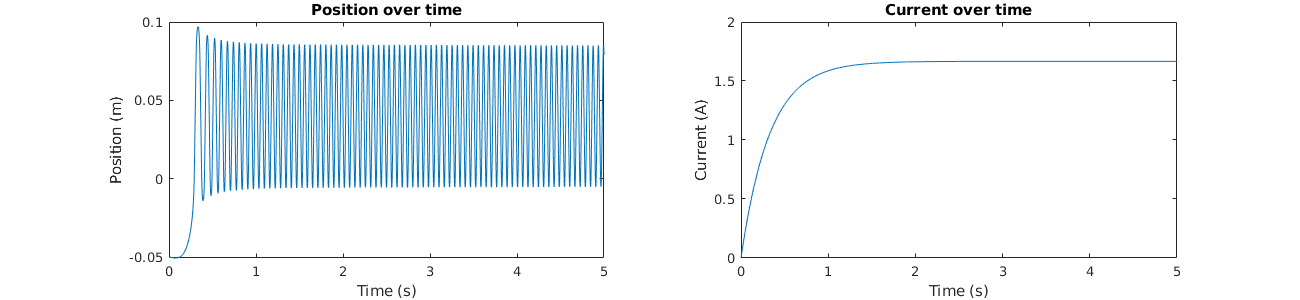

y0 = [0.05; 0; 0];
tspan = [0 5];

v = 5;

[t, y] = sim_magnet(tspan, y0, v, struct_params);

figure()
sgtitle("Simulation results: Varying winding numbers")

set(gcf, 'position', [0, 0, 1300, 300])
subplot(1, 2, 1)
plot(t, -y(:, 1))
title("Position over time")
xlabel("Time (s)")
ylabel("Position (m)")

subplot(1, 2, 2)
plot(t, y(:, 3))
title("Current over time")
xlabel("Time (s)")
ylabel("Current (A)")

function [t, y] = sim_magnet(tspan, y0, v_in, struct_params)
    g = 9.8; %m/s^2
        
    f_rates = @(t, y) ( ...
        rates_current(y, v_in)...
    );
    
    [t, y] = ode23(f_rates, tspan, y0);
    
    function rates = rates_current(y, v_in) % provide u as a function of y
        % Velocity
        rates(1,1) = y(2);
        
        % Acceleration
        rates(2,1) = F_iz(y(3), y(1), struct_params) + struct_params.m*g;
        
        % Change in current (inductor)
        rates(3, 1) = (1/struct_params.L)*(v_in - y(3)*struct_params.R);
    end
end
